## Manually Data Off-Sets

% figure
% plot(1:length(noise), noise,...
%     1:length(noise_plus_noise), noise_plus_noise,...
%     1:length(noise_plus_noise_abs_input), noise_plus_noise_abs_input)
% legend('Noise', 'Noise Plus Noise', 'Noise added at Absolute')
% title(figure_title);
% ylabel('Power [dB]');
% xlabel('Slices') ;

%%% 

active_SNR_minus20 = active_SNR - 20;
active_SNR_minus5 = active_SNR - 5;
active_SNR_minus10 = active_SNR - 10;
active_SNR_minus15 = active_SNR - 15;

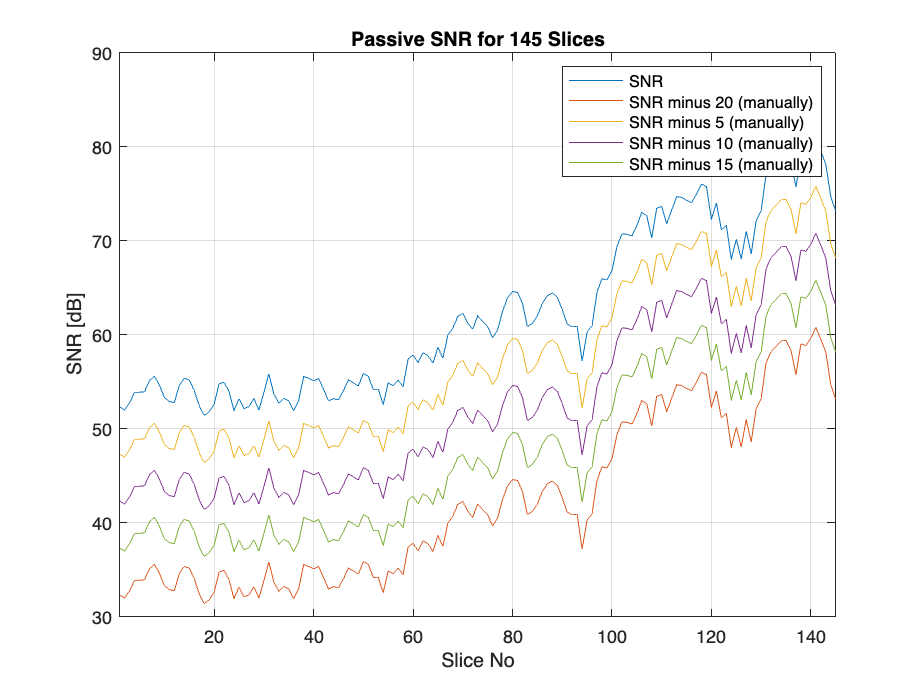

figure
active_SNR_delta = active_SNR - active_SNR_plus_noise;
%figure_title = (inputstructure.name + ' SNR for '...
%    + length(active_inputdata) + ' Slices: -5, -10, -15 & -20 [dB]');
fig = figure;
plot(1:length(active_SNR), active_SNR, ...
    1:length(active_SNR), active_SNR_minus20, ...
    1:length(active_SNR), active_SNR_minus5, ...
    1:length(active_SNR), active_SNR_minus10, ...
    1:length(active_SNR), active_SNR_minus15)
    %1:length(SNR_plus_noise), SNR_plus_noise, ...
    %1:length(SNR_delta), SNR_delta, ...
title(figure_title);
ylabel('SNR [dB]');
xlabel('Slice No') ;
legend("SNR", 'SNR minus 20 (manually)', 'SNR minus 5 (manually)', ...
    'SNR minus 10 (manually)', 'SNR minus 15 (manually)' )
% legend("SNR", 'SNR + Noise', 'SNR Delta', 'SNR minus 20 (manually)')
grid on
%ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([-inf length(active_SNR)]);   % Range Limit


mean(active_SNR);
mean(active_SNR_minus5);
mean(active_SNR_minus10);
mean(active_SNR_minus15);
mean(active_SNR_minus20);


## Playing with SNR Mean - Active

% mean(slices_range_doppler{1,1}, 'all')
mean_SNR = mean(active_SNR);
mean_SNR_plus_noise = mean(active_SNR_plus_noise)

mean_SNR_plus_noise = 50.2613

mean_SNR_delta = mean_SNR - mean_SNR_plus_noise

mean_SNR_delta = 12.0170

mean(active_signal)

ans = 41.7676

mean(active_signal_plus_noise)

ans = 41.7661

active_mean_noise = mean(active_noise)

active_mean_noise = -20.5108

active_mean_noise_plus_noise = mean(active_noise_plus_noise)

active_mean_noise_plus_noise = -8.4953

active_mean_noise_delta = active_mean_noise - active_mean_noise_plus_noise

active_mean_noise_delta = -12.0155

active_noise_plus_noise_db = 20*log10(active_noise_plus_noise_abs);
active_mean_noise_plus_noise_abs_converted = mean(active_noise_plus_noise_db)

active_mean_noise_plus_noise_abs_converted = -8.4953


% applying awgn at abs
active_slices_range_doppler_abs_plus_noise = createArrays(length(active_slices_range_doppler_abs),...
    size(active_slices_range_doppler_abs{1,1})); % absolute when populated
for i=1:length(active_slices_range_doppler_abs)
    active_slices_range_doppler_abs_plus_noise{1,i} = awgn(active_slices_range_doppler_abs{1,i}, active_user_defined_noise,...
        'measured'); % absolute + awgn
end
%%%


active_signal_plus_noise_abs_input=zeros(1,length(active_inputdata)); % [dB] once func populates
active_noise_plus_noise_abs_input=zeros(1,length(active_inputdata)); % [dB] once func populates
active_noise_plus_noise_abs_abs_input=zeros(1,length(active_inputdata)); % absolute mean noise (not dB) once func populates
active_SNR_plus_noise_abs_input=zeros(1,length(active_inputdata)); % [dB] once func populates
active_slices_range_doppler_plus_noise_abs_input = createArrays(length(active_inputdata), size(active_inputdata{1,1})); % [dB]
active_slices_range_doppler_plus_noise_abs_abs_input = createArrays(length(active_inputdata), size(active_inputdata{1,1})); % Absolute

for i=1:length(active_inputdata)
    [active_signal_plus_noise_abs_input(i),...
        active_noise_plus_noise_abs_input(i),...
        active_SNR_plus_noise_abs_input(i),...
        active_slices_range_doppler_plus_noise_abs_input{i},...
        active_signal_idx_plus_noise_abs_input(i),...
        active_noise_plus_noise_abs_abs_input(i),...
        active_slices_range_doppler_plus_noise_abs_abs_input{i}]=slice_SNR_abs_input(active_slices_range_doppler_abs_plus_noise{1,i}, active_roi_indices_rows, active_roi_indices_cols);
end  
mean(active_slices_range_doppler_abs{1,1}, 'all')

ans = 0.1409

%mean(active_inputdata_plus_noise_abs{1,1}, 'all')